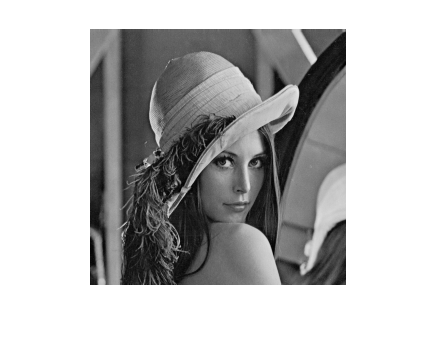




%Fourier transform filtering
image=imread("lena.bmp");
imshow(image);

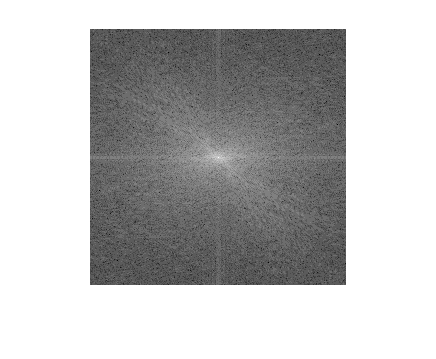

image_fourier_transform=fft2(image);
IF=fftshift(image_fourier_transform);
power_spectrum=abs(IF);
imshow(uint8(log(power_spectrum)),[]);

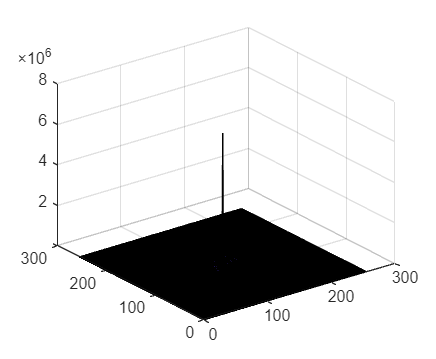

S=size(power_spectrum);
[X,Y]=meshgrid(0:1:(S(1)-1),0:1:(S(2)-1));
surf(X,Y,power_spectrum)

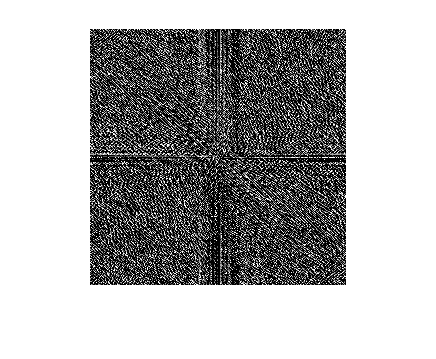

phase=atan2(imag(IF),real(IF));
imshow(uint8(phase),[]);

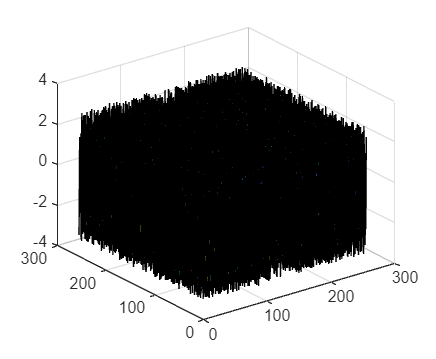

surf(X,Y,phase)

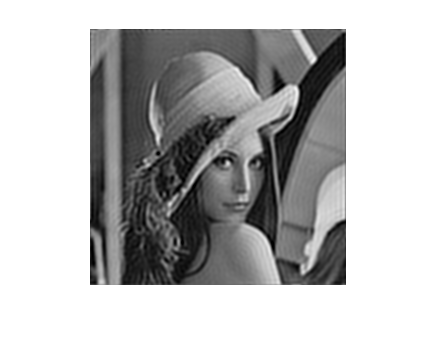


lowpass_filter=ideal_lowpass(50,S);
filter=IF.*lowpass_filter;
inverse=ifftshift(filter);
filter_image=ifft2(inverse);
imshow(uint8(filter_image))

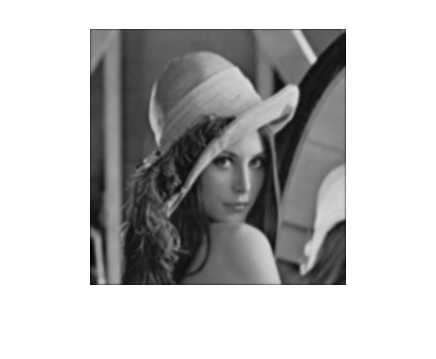


%Gaussian smoothing
Gaussian_filter=fspecial('gaussian',7,7/6);
image_filteredbyGaussian=conv2(image,Gaussian_filter,'same');
imshow(uint8(image_filteredbyGaussian))

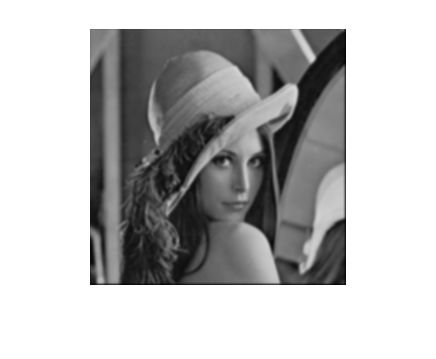

%myself
Gaussian_filter_myself=Gaussian(7,7/6);
image_filteredbyGaussian_myself=conv2(image,Gaussian_filter_myself,'same');
imshow(uint8(image_filteredbyGaussian_myself))

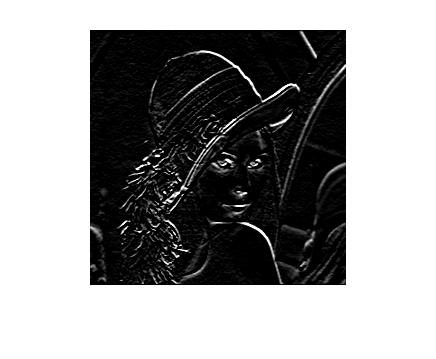



%Edge Enhancement

%Sobel
Sobel_operator=fspecial('sobel');
image_filtered_Sobel=conv2(image,Sobel_operator,'same');
imshow(uint8(image_filtered_Sobel));

%myself
sobelOperator=sobel();
image_filtered_Sobel_myself=conv2(image,sobelOperator,'same');
imshow(uint8(image_filtered_Sobel_myself));

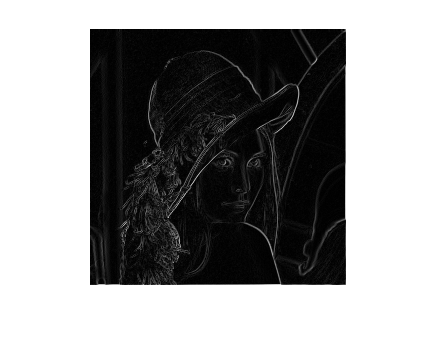

%gradient-based
x_gradient=[1 -1];y_gradient=[1;-1];
filtered_x=conv2(image,x_gradient,'same');
filtered_y=conv2(image,y_gradient,'same');
image_filtered_Gradient_based=sqrt(filtered_x.*filtered_x+filtered_y.*filtered_y);
imshow(uint8(image_filtered_Gradient_based));


%Simple edge detection
%using 2 times Gaussian
image_filteredbyGaussianone=conv2(image,Gaussian_filter,'same');
image_filteredbyGaussiantwo=conv2(image_filteredbyGaussianone,Gaussian_filter,'same');
imshow(uint8(image_filteredbyGaussian))

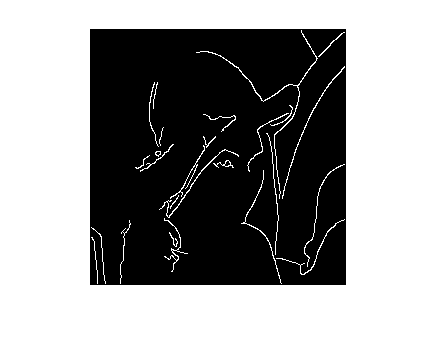

%canny edge detection
BW=edge(image,'canny',0.5,7/6);
imshow(BW, []);

function [SobelOperator]=sobel()
    SobelOperator=[1 2 1;0 0 0;-1 -2 -1];
end

function [GaussianFilter]=Gaussian(size,sigma)
    GaussianFilter=zeros(size,size);
    for i=1:size
        for j=1:size
            GaussianFilter(i,j)=1/(2*pi*sigma*sigma)*exp(-((i-(size-1)/2)*(i-(size-1)/2)+(j-(size-1)/2)*(j-(size-1)/2))/(2*sigma*sigma));
        end
    end
end



function [filter]=ideal_lowpass(R,S)
    filter=zeros(S(1),S(2));
    for i=1:S(1)
        for j=1:S(2)
            if sqrt(power(i-S(1)/2,2)+power(j-S(2)/2,2))<=R
                filter(i,j)=1;
            end
        end
    end

end

